## Import BIDS dataset

**Run 'eeglab' from the folder containing the eeglab codes. This will add all the relevant EEGLAB functions and directories to path.**

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "AMICA" v1.6.1 (see >> help eegplugin_amica)
EEGLAB: adding "BDFimport" v1.2 (see >> help eegplugin_bdfimport)
EEGLAB: adding "BIOSIG" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "FAA" v1.01 (see >> help eegplugin_faa)
EEGLAB: adding "FASTER" v1.2.4 (see >> help eegplugin_FASTER)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Fileio" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "PICARD" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Viewprops" v1.5.4 (see >> help eegplugin_viewprops)
EEGLAB: adding "bids-matlab-tools" v6.1 (see >> help eegplugin_bids)
EEGLAB: adding "bid

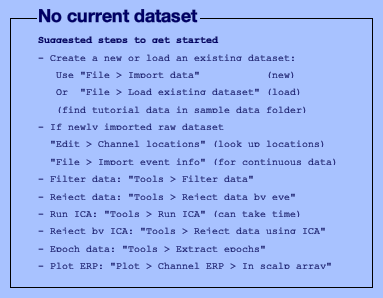

You are using the latest version of EEGLAB.


eeglab

**Steps:**

Load tutorial dataset

eeglabPath = fileparts(which('eeglab'))

pop_loadset(): loading file /System/Volumes/Data/data/matlab/eeglab/sample_data/eeglab_data.set ...
Reading float file '/System/Volumes/Data/data/matlab/eeglab/sample_data/eeglab_data.fdt'...


EEG = pop_loadset('filename','eeglab_data.set','filepath', fullfile(eeglabPath, 'sample_data'));
[ALLEEG, EEG, CURRENTSET] = eeg_store( ALLEEG, EEG, 0 );

Creating a new ALLEEG dataset 1


Create STUDY from single dataset

[STUDY ALLEEG] = std_editset( STUDY, ALLEEG, 'commands',{{'index',1,'subject','S1'}},'updatedat','off','rmclust','on' );

[STUDY ALLEEG] = std_checkset(STUDY, ALLEEG);
CURRENTSTUDY = 1; EEG = ALLEEG; CURRENTSET = [1:length(EEG)];

## BIDS_DL plugin export

pop_studydl(STUDY, ALLEEG, 'outputdir', fullfile(eeglabPath, 'ML_EXPORT'))

## Training with 12x12 interpolated data

## Create the datastore

train_imds = imageDatastore(fullfile(eeglabPath, 'ML_EXPORT', 'mat_files'), 'FileExtensions','.mat','IncludeSubfolders',true);

## Custom reader function

load_sample = @(x) x.Z_12; 
readfun = @(x) load_sample(load(x));


train_imds.ReadFcn = readfun;

## Preview the first sample of the datastore

sample = preview(train_imds);
fprintf('Sample size = %d, %d, %d\n', size(sample));

## Assign labels

train_label_info = readtable(fullfile(eeglabPath, 'ML_EXPORT', 'labels_local.csv'));
train_label_info_sorted = sortrows(train_label_info,1);
label_col =train_label_info_sorted.Var5; % sex of the subject has header Var5 
train_imds.Labels = categorical(label_col);

Note: the labels here have been sorted to match the order of Files (works for Mac/Linux and AWS - need to check for Windows).

## Define the network layers to be trained

channels = [12, 12]; %range of channels 
num_samples = 2048; %num of samples
image_size = [channels(1) channels(2) 2048]; 

num_labels = size(unique(train_imds.Labels),1);

layers = [
    imageInputLayer(image_size,"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],16,"Name","conv1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],16,"Name","conv2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],32,"Name","conv4","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv5","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],64,"Name","conv6","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],64,"Name","conv7","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(1024,"Name","fc1","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop1")
    fullyConnectedLayer(1024,"Name","fc2","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop2")
    fullyConnectedLayer(num_labels,"Name","fc3","WeightL2Factor",0)
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];

## Training the network

Define training settings. There are several [training options](https://in.mathworks.com/help/deeplearning/ref/trainingoptions.html) available. Try different options to improve performance.

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'MaxEpochs',40, ...
    'MiniBatchSize',40);
    

Train the network

eeg_net = trainNetwork(train_imds,layers,options);